% run sdrsetup

## Exercise 1

fs = 300e3; % this is the sample rate
fc = 90.8e6; % this is the center frequency

t = linspace(1,fs*5,fs*5+160);
t = t.';
x = zeros(fs*5,1); % empty vector to store data

% create object for RTL-SDR receiver
rx = comm.SDRRTLReceiver('CenterFrequency',fc, 'EnableTunerAGC', false, 'TunerGain', 35,  'SampleRate', fs);

counter = 1; % initialize a counter
while(counter < length(x)) % while the buffer for data is not full
    rxdata = rx();   % read from the RTL-SDR
    x(counter:counter + length(rxdata)-1) = rxdata; % save the samples returned
    counter = counter + length(rxdata); % increment counter
end
% the data are returned as complex numbers
% separate real and imaginary part, and remove any DC offset
y_I = real(x)-mean(real(x));
y_Q = imag(x)-mean(imag(x));
y_I2 = y_I;

## part c

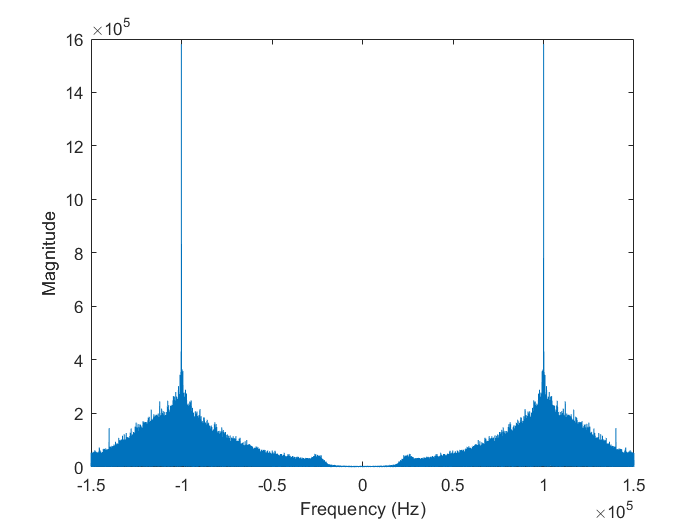

plot_FT(y_I2,fs); % Plot FFT of y_I
hold on;
xlabel("Frequency (Hz)")
ylabel("Magnitude")
hold off;

## part d

plot y_I in time domain

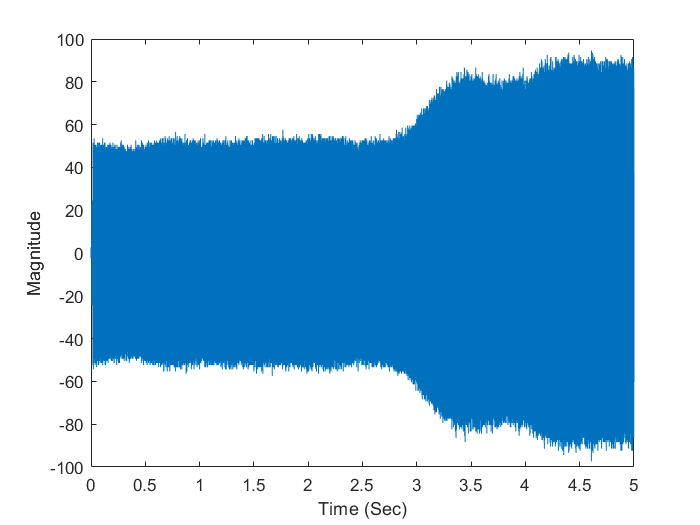

t2 = t./fs;
plot(t2,y_I2)
hold on;
xlabel("Time (Sec)")
ylabel("Magnitude")
hold off;

## part e

take derivative of signal

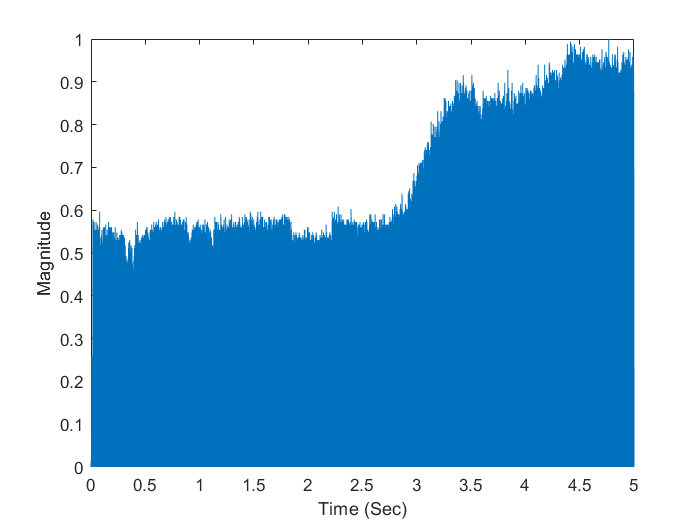

dydx = diff(y_I2(:))./diff(t(:));
% zero out negative components
dydx(dydx < 0) = 0;
% normalize it
dydx = dydx./max(dydx);
% plot it in time domain
plot(t(1:end-1,:)/fs,dydx)
hold on;
xlabel("Time (Sec)")
ylabel("Magnitude")
hold off;

## part f

create a LPF

vals = linspace(-5,5,101);
h = sinc(vals);
% plot_FT(h,fs)

output_I = conv(dydx, h);
% plot_FT(output_I,fs);

% plot in time domain both derivative and LPF
plot(t(1:end-1,:)/fs,dydx)
hold on;
plot(t(1:end,:)/fs,output_I(1:length(t),:))
xlabel("Time (Sec)")
ylabel("Magnitude")
legend("Derivative","LPF")
hold off;

## part g

get the output and play the sound

output = output_I - mean(output_I);
output_norm = output ./ (max(output).*10);

out = decimate(output_norm,4);
sound(out,fs/4)

## Exercise 2

## part b

fs = 300e3; % this is the sample rate
fc = 107.9e6; % this is the center frequency

t = linspace(1,fs*5,fs*5+160);
t = t.';
x = zeros(fs*5,1); % empty vector to store data

% create object for RTL-SDR receiver
rx2 = comm.SDRRTLReceiver('CenterFrequency',fc, 'EnableTunerAGC', false, 'TunerGain', 35,  'SampleRate', fs);

counter = 1; % initialize a counter
while(counter < length(x)) % while the buffer for data is not full
    rxdata = rx2();   % read from the RTL-SDR
    x(counter:counter + length(rxdata)-1) = rxdata; % save the samples returned
    counter = counter + length(rxdata); % increment counter
end
% the data are returned as complex numbers
% separate real and imaginary part, and remove any DC offset
y_I_2 = real(x)-mean(real(x));
y_Q = imag(x)-mean(imag(x));

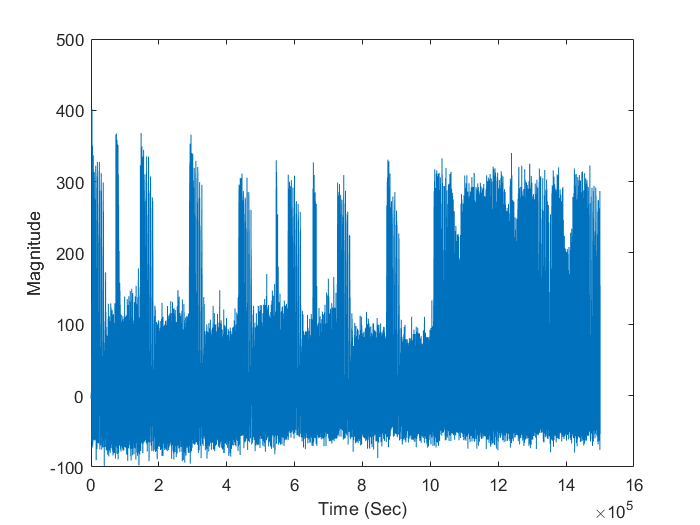

%take derivative of y_I and y_Q
dyIdx =  diff(y_I_2(:))./diff(t(:));
dyQdx = diff(y_Q(:))./diff(t(:));

% plug into m_hat equation
m_hat = dyQdx .* y_I_2(1:length(dyQdx)) - (dyIdx .* y_Q(1:length(dyQdx)));

% plot m_hat in time domain
plot(m_hat)
hold on
xlabel("Time (Sec)")
ylabel("Magnitude")
hold off

plot m_hat in freq domain

plot_FT(m_hat/max(m_hat),fs)

ans = 	1.0e+05 *

  -0.0003 + 0.0008i
  -0.0006 + 0.0010i
   0.0007 - 0.0005i
  -0.0010 - 0.0006i
  -0.0013 + 0.0001i
   0.0001 - 0.0008i
   0.0014 + 0.0007i
  -0.0009 + 0.0009i
   0.0004 - 0.0005i
  -0.0010 - 0.0006i


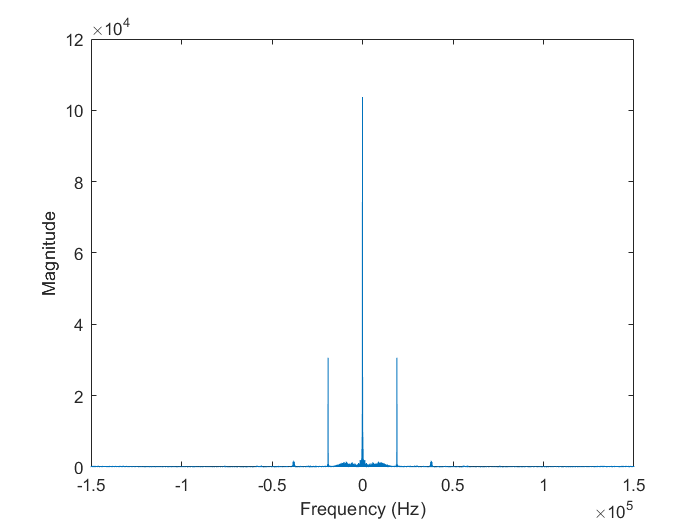

hold on
xlabel("Frequency (Hz)")
ylabel("Magnitude")
hold off

play m_hat sound

out_m = 0.4 * decimate(m_hat,4) / max(m_hat);
sound(out_m,fs/4)